# Using neural decoding to understand how the brain processes information

A central goal of Neuroscience research is to understand how neural activity enables animals to perform complex behaviors. To study this, neuroscientists make different types of neural recordings, including functional magnetic resonance imaging (fMRI) and electroencephalography (EEG) recordings from humans, and recording action potential of individual neurons. Once this data is recorded, neuroscientists then need to apply a data analyses to turn the recorded signals into information that can lead to an understanding of how the brain is processing information. 

One method that has been shown to be very useful for interpreting neural activity is called *neural decoding* (the method is also referred to as *multi-voxel pattern analysis* by the fMRI community). The purpose of this tutorial is to explain what neural decoding is and how to run a decoding analysis in MATLAB. 

## An example experiment

To illustrate how neural decoding works, we will use data from an experiment run by Ying Zhang and Bob Desmione at MIT [1], which will will refer to as the Zhang-Desimone experiment. On each trial in this experiment, a monkey fixed on a dot for 500 ms, and then one of seven possible images was shown to the monkey for 500 ms (figure 1).  While the monkeys viewed these images, Ying recorded the spiking activity from 132 neurons in the inferior temporal cortex (IT) which is a brain region thought to be involved with objet recognition. Each experimental trial type was repeated ~60 times to collect a data set that had spiking activity from 420 trials (7 trials * 60 repeitions = 420 trials total). (The actual experiment was a bit more complex and consisted of showing the images at different locations and also an attentional manipulation but we will ignore this for now). 

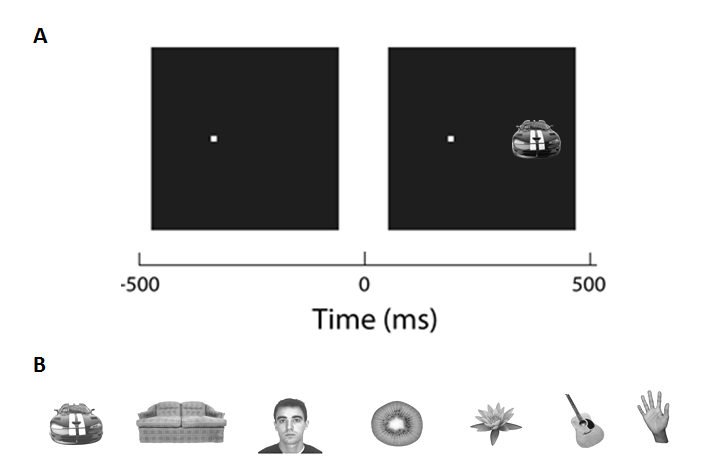

***Figure 1.****  An example experiment run by Ying Zhang and Bob Desimone at MIT. ****A****, An example of an experimental trial where the monkey fixated for 500 ms and then was showng a stimulus for 500 ms. ****B****, the seven diffrent stimuli that could be shown to the monkey. Each stimulus was shown 60 times (20 times at each location) while the spiking activity of 132 neurons was recorded. *

## What is neural decoding?

Neural decoding is a data analysis method where a computer program, called a *pattern classifier*, uses neural activity to predict what experimental conditions are present on a particular experimental trial. The the pattern classifier can predict what experimental conditions are present based on neural activity at a level that is above chance, this means that there is a reliable relationship between the neural activity an different experimental conditions, or put another way, there is information about the experimental conditions in the neural activity. 

Figure 2 illustrates how this process works on one trial from the Zhang-Desime experiment. On the trial shown in figure 2, a monkey was shown an image of a kiwi (Fig. 2A) while 132 neurons were recorded (Fig. 2B). The activity of these neurons was then fed into a pattern classifier (Fig. 2C) and the classifier predicted that a kiwi was present on this trial (Fig 2D). Since in a kiwi was in fact shown on this trial, the prediction made by the classifier is marked as being corrected (Fig. 2E). This process is then repeated for many different trials, and the percentage of correct predictions is reported. If the pattern classifer was merely guessing which image was shown on each trial, then we would expect correct predictions to be made on approximate 1 out of every 7 trials, since there are 7 different possible images the classifier has to choose between. If the prediction accuracy is well above 1/7, then the classifier is unlikely to be guessing, which means there is a reliable relationship between the stimuli and the neural activity. 

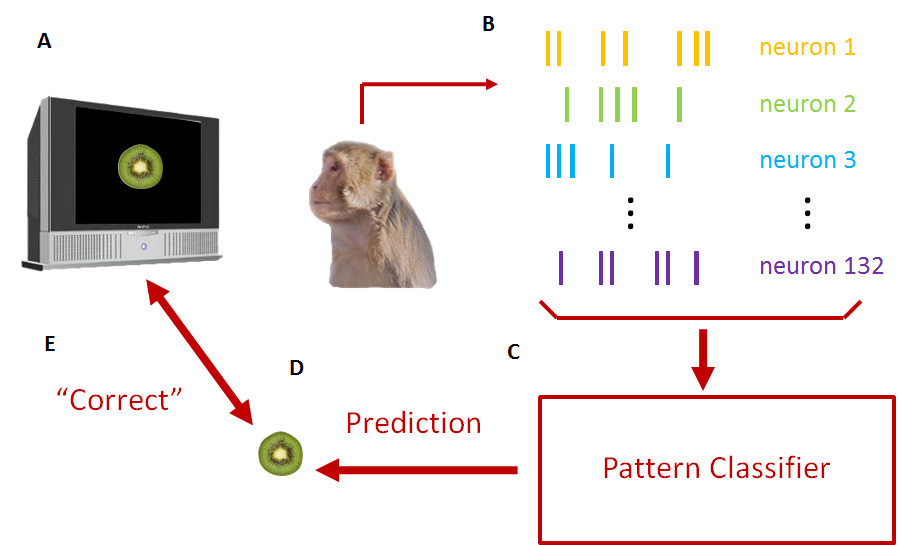

***Figure 2.****  An example showing a decoding analysis for one trial form the Zhang-Desimone experiment. ****A****, On this trial, the monkey is shown an image of a kiwi. ****B****, While the monkey views the image, the spiking activity of 132 neurons is recorded. ****C****, This neural activity is fed into a pattern classifier.**** D****, The pattern classifier then makes a prediction about what image it thinks is present based on the neural activity. In this example, the classifier predicted the image was of a kiwi.  ****E****, The prediction of the classifier is then compared to the image that was actually shown to the monkey. In this example, the classifiers prediction was correct, so we make it a correct prediction. This process (steps A to E) is repeated over many trials, and the average prediction accuracy is reported as the final statistic from this analysis. If the average prediciton accuracy is well above chance, then it means there is a reliable relationship between the neural activity and the different images, or in other words, the neural activity has information about the stimuli [2].*

## Training the classifier to make predictions

In order for the pattern classifier to be able to make correct predictions, the classifier must be able to *learn* the relationship between between different patterns of neural activity and different experimental conditions.  To do this, the neuron recordings from different trials are divided into two non-overlapping sets of data. One set of data is called the *training set *and is used by the pattern classifier to learn the relationship between the neural recordings and experimental conditions. The second set of data is called the *test set*, and the classifier must take this test set and try to correct predict which experimental conditions were present on all of the trials in this set. Again, if the classifier can make correct predictions on the test set, it means there is a reliable relationship between the neural activity and the different experimental conditions. In a typical decoding analysis, a '*cross-validation*' process is used where the process of dividing the data into different training and test sets is repeated many times, and the final decoding accuracy is averaged over many different training and test splits. For more information about how decoding works, see reference [3]. 

## Downloading and setting up the Neural Decoding Toolbox (NDT) 

In order to illustrate how to run a decoding analyses on the Zhang-Desimone data, we will use MATLAB and the Neural Decoding Toolbox (NDT) [4]. You can download the NDT and set the toolbox path using the following steps:

- Register to download the toolbox by going to  [http://www.readout.info/wp-login.php?action=register](http://www.readout.info/wp-login.php?action=register) and filling out the form. Once you fill out the form you will receive an email with a link you can click on to finish confirming your registration. 

- After have an account, you should log into the [www.readout.info](www.readout.info) website. You can then download the toolbox from [http://www.readout.info/downloads/download-the-toolbox/](http://www.readout.info/downloads/download-the-toolbox/)  and clicking on the 'Downlad the latest version of the Neural Decoding Toolbox' link. 

- You should download the data from Zhang-Desiomone experiment from [http://www.readout.info/downloads/datasets/zhang-desimone-7-object-dataset/](http://www.readout.info/downloads/datasets/zhang-desimone-7-object-dataset/) by clicking on the 'Download the Zhang-Desimone 7 object dataset' link. 

- After the NDT and the Zhang-Desimone .zip files have been downloaded, unzip them and place the two folders in a directory where you would like to do your analyses; e.g., you should have a directory that contaings the folders with names ndt.1.0.4/ and Zhang_Desimone_7objects_raster_data/. Then open MATLAB, and set your MATLAB current folder to be the folder that contains these directories. 

- Finally, run the following command to set the MATLAB path to contain the NDT:

% add the path to the NDT so add_ndt_paths_and_init_rand_generator can be called
toolbox_basedir_name = 'ndt.1.0.4/';
addpath(toolbox_basedir_name);
 
% add the NDT paths using add_ndt_paths_and_init_rand_generator
add_ndt_paths_and_init_rand_generator

toolbox_basedir_name = '/cbcl/cbcl01/emeyers/work/projects/readout/NDT_tutorial_for_Ellen/NDT_tutorial/ndt.1.0.4/'

initializing the matlab random number generator to an aribrary clock value, i.e., the 'rand' function should now work properly


If everything has worked correctly you should see a message that says: *'initializing the matlab random number generator to an aribrary clock value, i.e., the 'rand' function should now work properly'*

## Binned the Zhang-Desimone data

When we described the decoding process above, we said that the pattern classifier was trained and tested using neural spiking data. However, usually when we do a decoding analysis on neural spiking data we don't pass the classifer the exact spike times, but instead we pass the classifier a list of the number of spikes that occurred in a given time window on each trial  - i.e., we pass the classifier the *spike count firing rate* rather than the exact spike times. The Zhang-Desimone data you downloaded  contains exact spike times, so for the first step in our data analysis we need to *'bin the data'* by converting the spike times into a spike count firing rate. 

Rather than converting all the spike times into a single firing rate on each trial, we typically bin the data from a trial into a number of sub-bins. For example, each experimental trial in Zhang-Desimone data is 1 second long (i.e., 500 ms of fixation and 500 ms of stimulus presentation), and rather than binned the data into a single 1 second bin that counts all the spikes that occured on a trial, we can instead bin the data into a sequence of 100 ms bins that span the full 1 second trial length; if the bins do not overlap, we would have 10 bins of 100 ms length that will span the 1 second trial. The coding analysis will then be run separately on each spike counts in each bin to get an estimate of how the information varies as a funciton of time; for the Zhang-Desimone data, we should not expect to be able to decode what stimulus is present during the fixation period prior to the stimulus onset (since the monkey is not psychic) but if there is information in the neural activity, we should be able to decode the stimulus sometime after it has been presented. 

Finally, we can also have the bins overlap to get a smoother estimate of the information as a function of time.  To do this we need to specify the *sampling interval *which says how often we should create bins. For example, if we use bins that are 100 ms in length, and a sampling interval of 50 ms, then each adjacent bin will have a 50% overlap, and there will be 21 spike count bins with rnages of 1-100 ms, 51-150 ms, 101-150 ms, etc.  Figure 3 illustrates this binning process. 

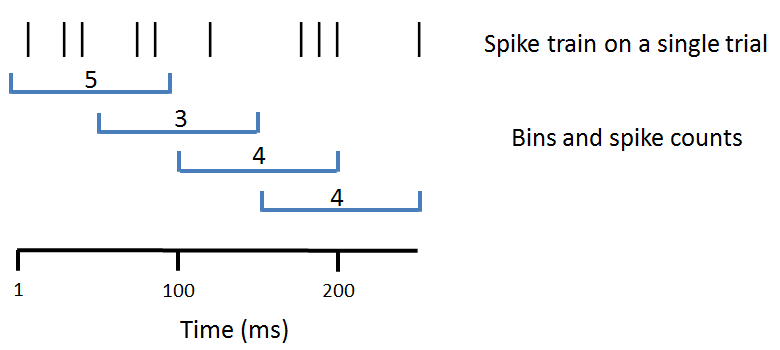

***Figure 3.**** Illustration of how spike trains are binned into spike count firing rates. The upper sequence of vertical bars represents the times of spikes in the first 250 ms of a spike train from a single trial.  The blue brackets represent four 100 ms bins, and the numbers in the brackets represent the spike counts in each bin. The bins are sampled every 50 ms and thus they overlap. The output of the binning process is a sequence of spike counts that start with 5, 3, 4, 4, etc. This binning process will be done for every trial and for all neurons, and this binned test data will be passed the a pattern classifier to make predictions about what happened on each trial. *

To bin the data using the NDT, we can use the function *create_binned_data_from_raster_data *as follows: 

% The name of the directory that has the spike data files
spike_file_directory_name = 'Zhang_Desimone_7objects_raster_data/';

% A name to use when the results as saved
save_prefix_name = 'Binned_ZD_data';

bin_size = 100;
sampling_interval = 50;
 
create_binned_data_from_raster_data(spike_file_directory_name, save_prefix_name, bin_size, sampling_interval);


 Binning the data: 1 of 132
 Binning the data: 2 of 132 Binning the data: 3 of 132 Binning the data: 4 of 132 Binning the data: 5 of 132 Binning the data: 6 of 132 Binning the data: 7 of 132 Binning the data: 8 of 132 Binning the data: 9 of 132 Binning the data: 10 of 132 Binning the data: 11 of 132 Binning the data: 12 of 132 Binning the data: 13 of 132 Binning the data: 14 of 132 Binning the data: 15 of 132 Binning the data: 16 of 132 Binning the data: 17 of 132 Binning the data: 18 of 132 Binning the data: 19 of 132 Binning the data: 20 of 132 Binning the data: 21 of 132 Binning the data: 22 of 132 Binning the data: 23 of 132 Binning the data: 24 of 132 Binning the data: 25 of 132 Binning the data: 26 of 132 Binning the data: 27 of 132 Binning the data: 28 of 132 Binning the data: 29 of 132 Binning the data: 30 of 132 Binning the data: 31 of 132 Binning the data: 32 of 132 Binning the data: 33 of 132 Binning the data: 34 of 132 Binning the data: 35 of 132 Binning the data: 36 of 13

If the function works correctly it should create an output file called *Binned_ZD_data_100ms_bins_50ms_sampled.mat *which contains the binned data. We will use this file in subsequent decoding analyses. 

## Running a decoding analysis using the NDT

cross-validation

## Basic decoding analyses

Explain Zhang 7 object experiment and how to analyze data from it

## Testing position invariance

## Additional analyses 

## References 

[1] Zhang Y, Meyers E, Bichot N, Serre T, Poggio T, and Desimone R (2011). Object decoding with attention in inferior temporal cortex. *Proceedings of the National Academy of Sciences*, 108:8850-8855.

[2] Quian Qurioga R, and Panzerri S (2009). Extracting information from neuronal populations: information theory and decoding approaches. *Nature Reviews Neuroscience*, 10(3):173-85.

[3] Meyers E, and Kreiman G (2011). Tutorial on Pattern Classification in Cell Recording. In: Visual population codes. Kreigeskorte, N., and Kreiman, G. (eds.), MIT Press.

[4] Meyers E (2013). The Neural Decoding Toolbox. *Frontiers in Neuroinformatics*, 7:8.